POSITION_VEC = [3,3,3.75,3.25];

## Riley's Data

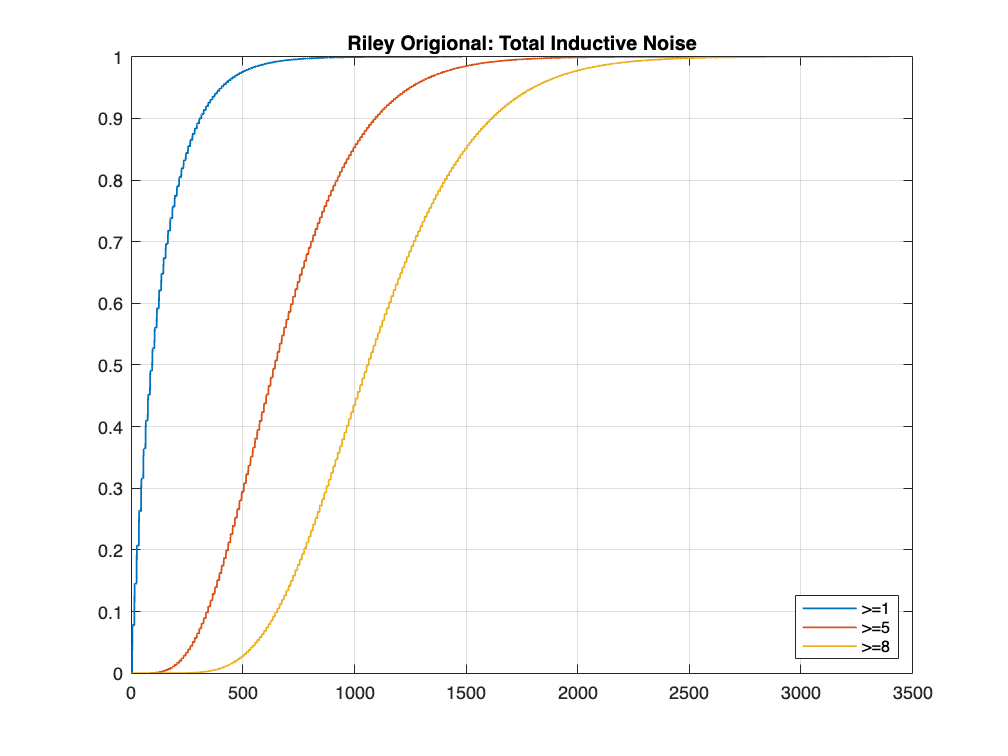

data = readmatrix('Data/Riley/Inductive1.csv');
resist_riley_1_x=data(1:2:end);
resist_riley_1_y=data(2:2:end);

data = readmatrix('Data/Riley/Inductive5.csv');
resist_riley_5_x=data(1:2:end);
resist_riley_5_y=data(2:2:end);

data = readmatrix('Data/Riley/Inductive8.csv');
resist_riley_8_x=data(1:2:end);
resist_riley_8_y=data(2:2:end);

plot(resist_riley_1_x,resist_riley_1_y, ...
     resist_riley_5_x,resist_riley_5_y, ...
     resist_riley_8_x,resist_riley_8_y);
grid on;
title("Riley Origional: Total Inductive Noise")
legend(">=1",">=5",">=8","Location","southeast");

## Jonah's Data

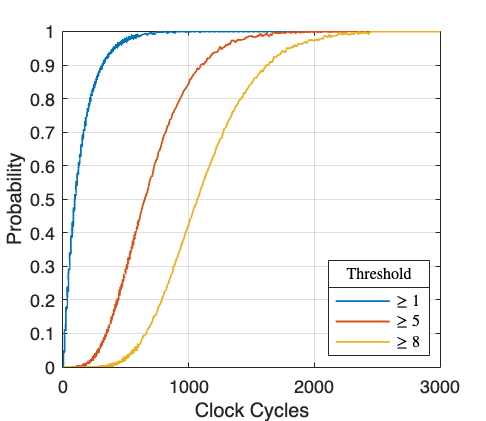

data = readmatrix('Data/Jonah/Inductive/pre_2x2_1.csv');
resist_jonah_1_x=data(1:2:end);
resist_jonah_1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Inductive/pre_2x2_5.csv');
resist_jonah_5_x=data(1:2:end);
resist_jonah_5_y=data(2:2:end);

data = readmatrix('Data/Jonah/Inductive/pre_2x2_8.csv');
resist_jonah_8_x=data(1:2:end);
resist_jonah_8_y=data(2:2:end);

fig = figure("Units","inches","Position",POSITION_VEC);

plot(resist_jonah_1_x,resist_jonah_1_y, ...
     resist_jonah_5_x,resist_jonah_5_y, ...
     resist_jonah_8_x,resist_jonah_8_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
xlim([0,3000]);
leg = legend(["$\ge 1$","$\ge 5$","$\ge 8$"],"Location","southeast","Interpreter","Latex");
title(leg, "Threshold", "Interpreter","latex");
exportgraphics(fig, "VMCAI_25/2x2_inductive_final.png", "Resolution",300);

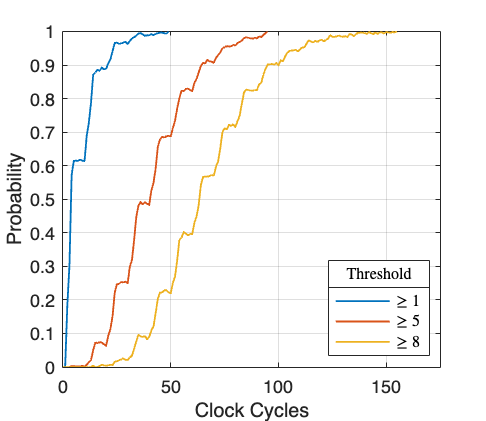

data = readmatrix('Data/Jonah/Inductive/uniform_3x3_1.csv');
resist_jonah_1_x_3x3=data(1:2:end);
resist_jonah_1_y_3x3=data(2:2:end);

data = readmatrix('Data/Jonah/Inductive/uniform_3x3_5.csv');
resist_jonah_5_x_3x3=data(1:2:end);
resist_jonah_5_y_3x3=data(2:2:end);

data = readmatrix('Data/Jonah/Inductive/uniform_3x3_8.csv');
resist_jonah_8_x_3x3=data(1:2:end);
resist_jonah_8_y_3x3=data(2:2:end);

fig = figure("Units","inches","Position",POSITION_VEC);

plot(resist_jonah_1_x_3x3,resist_jonah_1_y_3x3, ...
     resist_jonah_5_x_3x3,resist_jonah_5_y_3x3, ...
     resist_jonah_8_x_3x3,resist_jonah_8_y_3x3);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
xlim([0,175]);
leg = legend(["$\ge 1$","$\ge 5$","$\ge 8$"],"Location","southeast","Interpreter","Latex");
title(leg, "Threshold",'Interpreter','latex')
exportgraphics(fig, "VMCAI_25/3x3_inductive_final.png", "Resolution",300);

## Comparing Jonah and Riley's Inductive Noise

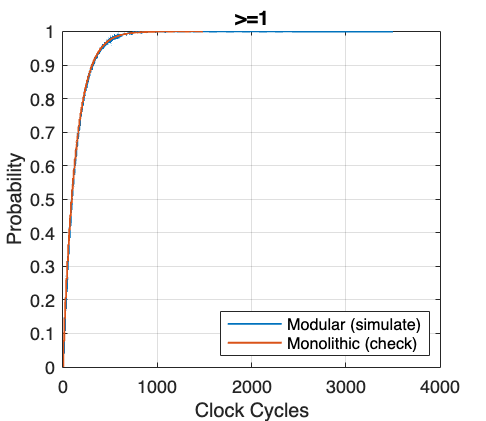

plot(resist_jonah_1_x,resist_jonah_1_y, ...
    resist_riley_1_x,resist_riley_1_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=1");
legend("Modular (simulate)","Monolithic (check)","Location","southeast");

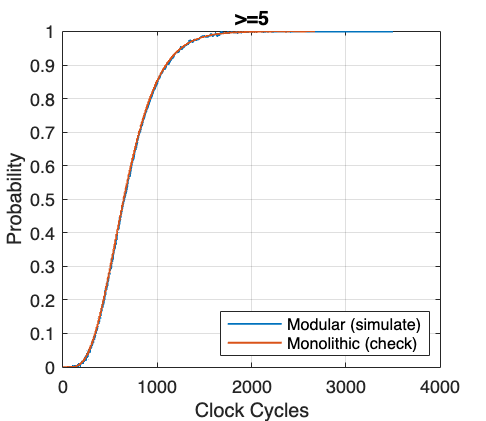


plot(resist_jonah_5_x,resist_jonah_5_y, ...
    resist_riley_5_x,resist_riley_5_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=5");
legend("Modular (simulate)","Monolithic (check)","Location","southeast");

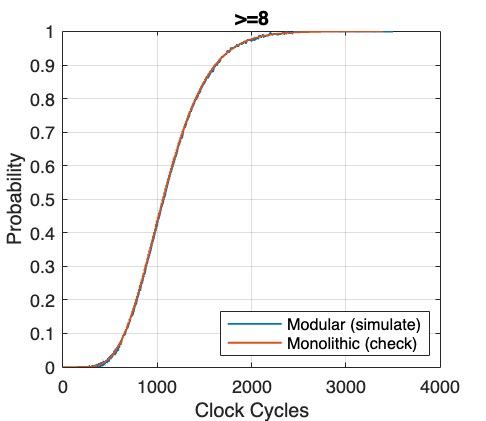


plot(resist_jonah_8_x,resist_jonah_8_y, ...
    resist_riley_8_x,resist_riley_8_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
title(">=8");
legend("Modular (simulate)","Monolithic (check)","Location","southeast");

fig_r = figure(Units="inches", Position=POSITION_VEC);
hold on;
p(1) = plot(nan,nan,'b');
plot(resist_riley_1_x,resist_riley_1_y, 'b--', 'LineWidth',1.0);
p1(1) = plot(resist_riley_1_x,resist_riley_1_y, 'b--', 'LineWidth',1);
p1(2) = plot(resist_riley_5_x,resist_riley_5_y, 'b', 'LineWidth',1, 'Marker','+', 'MarkerIndices',1:35:length(resist_riley_5_x));
p1(3) = plot(resist_riley_8_x,resist_riley_8_y, 'b', 'LineWidth',1, 'Marker','square', 'MarkerIndices',1:25:length(resist_riley_8_x));
%plot(resist_riley_20_x,resist_riley_20_y, 'b');

p(2) = plot(nan,nan,'r');
plot(resist_jonah_1_x,resist_jonah_1_y, 'r--', 'LineWidth',1);
plot(resist_jonah_5_x,resist_jonah_5_y, 'r', 'LineWidth',1, 'Marker','+', 'MarkerIndices',1:35:length(resist_jonah_5_x));
plot(resist_jonah_8_x,resist_jonah_8_y, 'r', 'LineWidth',1, 'Marker','square', 'MarkerIndices',1:25:length(resist_jonah_8_x));
%plot(resist_jonah_20_x,resist_jonah_20_y, 'r');
leg1 = legend(p, ["Monolithic", "Modular"], "Location","southeast",'Interpreter','latex');
title(leg1, "Model");

grid on
xlabel("Clock Cycle");
ylabel("Probability");
xlim([0, 2000]);

ax2 = axes('position',get(gca,'position'),'visible','off');
hold on
p2(1) = plot(nan,nan,'--','Color','black');
p2(2) = plot(nan,nan,'Marker','+','Color','black');
p2(3) = plot(nan,nan,'Marker','square','Color','black');
hold off

leg2 = legend(ax2, p2, ["$\ge 1$", "$\ge 5$", "$\ge 8$"], 'Location','east', "Interpreter","latex");

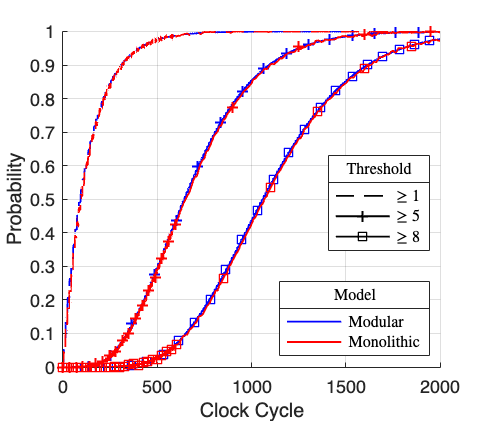

title(leg2, "Threshold");

exportgraphics(fig_r, "VMCAI_25/final_induct_comparison.png", "Resolution",300);